#  Laboratorio 4

Camilo Borda Brian Saiz

### Sistemas de referencia según la convención DHstd.

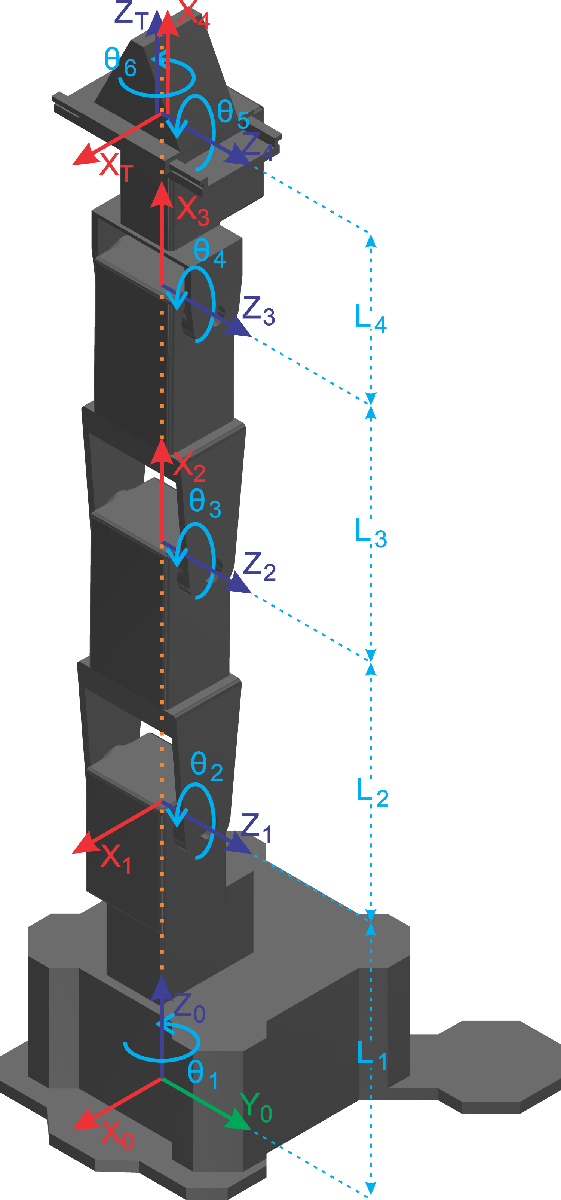

### Parámetros de acuerdo con la convención DHstd.


$$\left\lbrack \begin{array}{cccccc}
i & \theta_i  & d_i  & a_i  & \alpha_i  & \mathrm{offset}\\
1 & \theta_1  & L_1  & 0 & \frac{\pi }{2} & 0\\
2 & \theta_2  & 0 & L_2  & 0 & \frac{\pi }{2}\\
3 & \theta_3  & 0 & L_3  & 0 & 0\\
4 & \theta_3  & 0 & L_4  & 0 & 0
\end{array}\right\rbrack$$


### Presente el robot en las configuraciones qz = [0 0 0 0] 

l=[145,107,107,80];  %[mm]
offset = [0 pi/2 0 0];
L(1) = Link('revolute','alpha',pi/2,'a', 0  ,'d',l(1),'offset',offset(1));
L(2) = Link('revolute','alpha',0,   'a',l(2),'d',0   ,'offset',offset(2));
L(3) = Link('revolute','alpha',0,   'a',l(3),'d',0   ,'offset',offset(3));
L(4) = Link('revolute','alpha',0,   'a',l(4),'d',0   ,'offset',offset(4));
Robot2=SerialLink(L,'name','R2')

 
Robot2 = 
 
R2:: 4 axis, RRRR, stdDH, slowRNE                                
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|        145|          0|     1.5708|          0|
|  2|         q2|          0|        107|          0|     1.5708|
|  3|         q3|          0|        107|          0|          0|
|  4|         q4|          0|         80|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


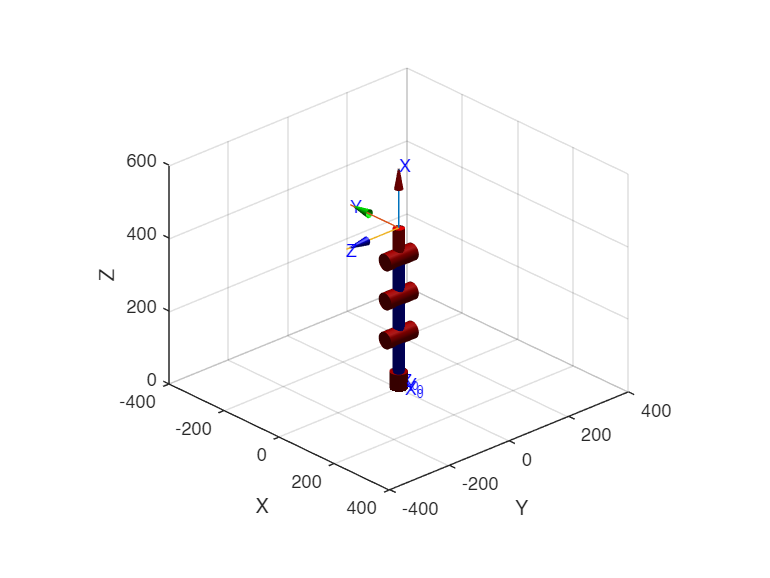

ws = [-1 15];
close all
q1 = [0 0 0 0];
figure(1)
Robot2.plot(q1,'notiles','noname');
hold on
trplot (eye(3),'rgb','arrows','length',15,'frame','0')
axis([repmat(ws,1,2) -4 5])
hold off

xlim([-400 400])
ylim([-400 400])
zlim([0 600])

view([47 26])

### Presente el robot en las configuraciones qz = [-pi/9 pi/9 -pi/9 pi/9] 

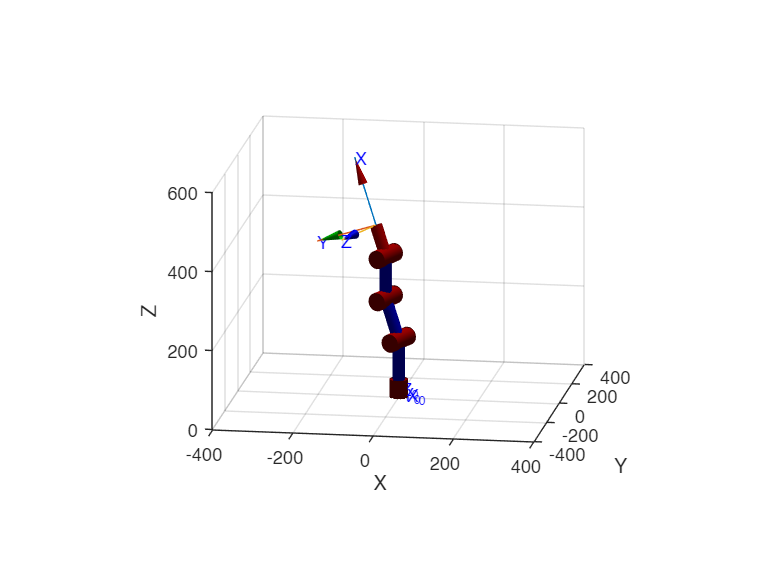

close all
q2 = [-pi/9 pi/9 -pi/9 pi/9];
figure(1)
Robot2.plot(q2,'notiles','noname');
hold on
trplot (eye(3),'rgb','arrows','length',15,'frame','0')
axis([repmat(ws,1,2) -4 5])
hold off

xlim([-400 400])
ylim([-400 400])
zlim([0 600])

view([9 14])

### Presente el robot en las configuraciones qz = [pi/6 -pi/6 pi/6 -pi/6] 

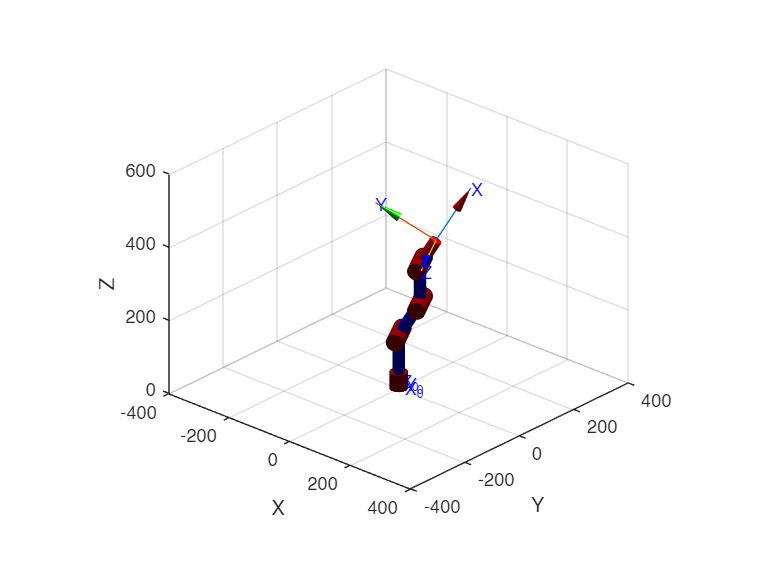

close all
q3 = [pi/6 -pi/6 pi/6 -pi/6];
figure(1)
Robot2.plot(q3,'notiles','noname');
hold on
trplot (eye(3),'rgb','arrows','length',15,'frame','0')
axis([repmat(ws,1,2) -4 5])
hold off

xlim([-400 400])
ylim([-400 400])
zlim([0 600])

view([42 26])

### Presente el robot en las configuraciones qz = [-pi/2 pi/12 -11*pi/36 17*pi/180] 

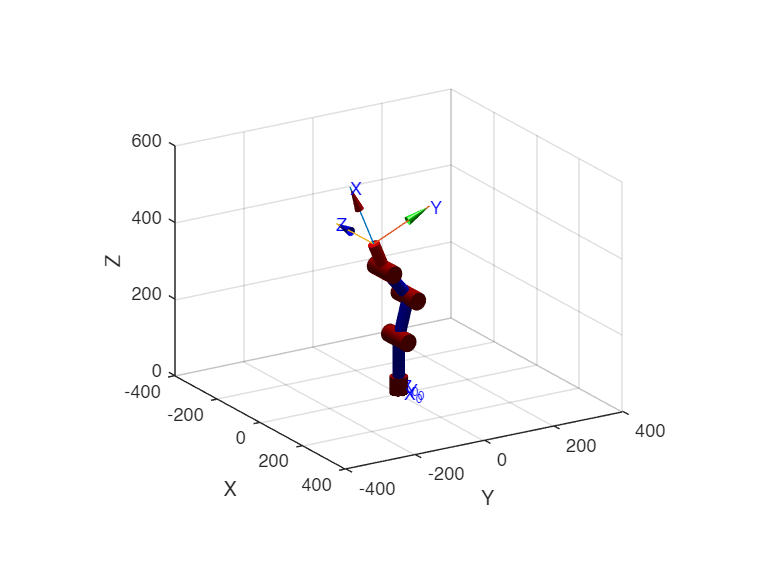

close all
q4 = [-pi/2 pi/12 -11*pi/36 17*pi/180];
figure(1)
Robot2.plot(q4,'notiles','noname');
hold on
trplot (eye(3),'rgb','arrows','length',15,'frame','0')
axis([repmat(ws,1,2) -4 5])
hold off

xlim([-400 400])
ylim([-400 400])
zlim([0 600])

view([58 20])

### Presente el robot en las configuraciones qz = [-pi/2 pi/4 -11*pi/36 pi/4] 

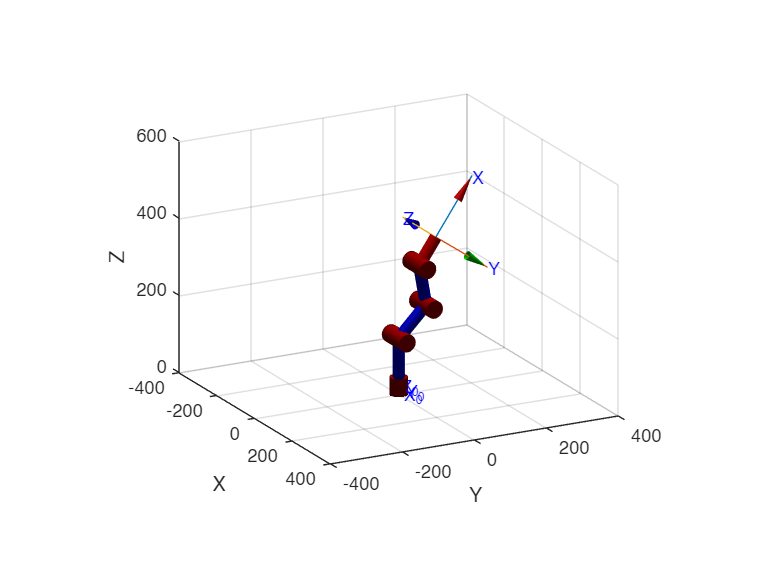

close all
q5 = [-pi/2 pi/4 -11*pi/36 pi/4];
figure(1)
Robot2.plot(q5,'notiles','noname');
hold on
trplot (eye(3),'rgb','arrows','length',15,'frame','0')
axis([repmat(ws,1,2) -4 5])
hold off

xlim([-400 400])
ylim([-400 400])
zlim([0 600])

view([62 18])

% Matriz de transformación Homogénea
    MTHCorke = Robot2.fkine(q1); %MTH hasta el TCP.
    disp(MTHCorke)

    6.123e-17        -1         0   1.8e-14
    6.123e-17 3.749e-33        -1   1.8e-14
            1 6.123e-17 6.123e-17       439
            0         0         0         1
